## [Optimization Method: FOPDT to Data](https://apmonitor.com/pdc/index.php/Main/FirstOrderOptimization)

A first-order linear system with time delay is a common empirical description of many stable dynamic processes. The equation


$$\tau_p \frac{dy(t)}{dt} = -y(t) + K_p u\left(t-\theta_p\right)$$


has variables *y(t)* and *u(t)* and three unknown parameters.


$$K_p \quad \mathrm{= Process \; gain}$$



$$\tau_p \quad \mathrm{= Process \; time \; constant}$$



$$\theta_p \quad \mathrm{= Process \; dead \; time}$$


These variables may be adjusted to match data. An explicit solution to the above equation for each time step *j* is:

$y_j = e^{\frac{-\Delta\,t}{\tau_p}} \left(y_{j-1}-y_0\right) + \left(1-e^{\frac{-\Delta\,t}{\tau_p}}\right) \, K_p \, \left(u_{j-\theta_p-1}-u_0\right) + y_0
$where $\Delta t$ is the time step length, $y_0$ is the initial output or steady state condition, $u_0$ is the initial input or steady state condition, $y_{j-1}$ and $u_{j-1}$ are values from the prior step and $\theta_p$ is the dead-time measured in number of time steps. When the matching process employs optimization, a model prediction is aligned with the measured values with the use of a solver. The solver often minimizes a measure of the alignment such as a sum of squared errors or sum of absolute errors. An optimization solver for Python is the SciPy.Optimize.Minimize function. Below is a tutorial on solving nonlinear optimization problems in Python.

The optimization can be applied to dynamic models as well. Below are tutorial examples using Excel or Python to adjust the parameters to fit the model predictions to data. Unlike a [**graphical method to fit an FOPDT model**](https://apmonitor.com/pdc/index.php/Main/FirstOrderGraphical), optimization methods do not require a single step response but may include any sequence of input changes that produce a response in the output.

Fit FOPDT to Data with Excel

Fit FOPDT to Data with Python

An alternative to the graphical fitting approach is to use optimization to best match an FOPDT model to data or a more complex model. A common objective is to minimize a sum of squared error that penalizes deviation of the FOPDT model from the data. The optimization algorithm changes the parameters $K_p$, $\tau_p$, $\theta_p$ to best match the data at specified time points.

## Generate Simulated Data from Model

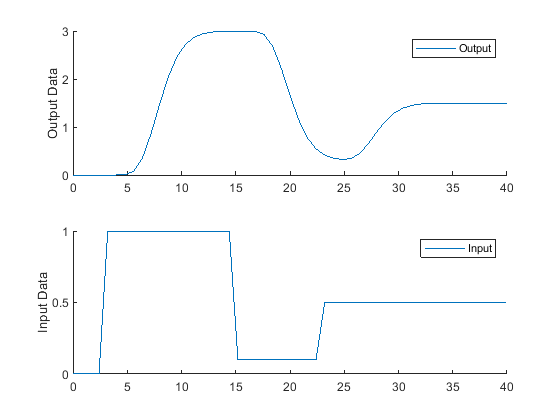

global yp ns delta_t u tvals yp0 u0 %Define variables as global so they can pass through functions 
%and fminsearch will not attempt to optimize them

% specify number of steps
ns = 50;
% define time points
t = linspace(0,40,ns+1);
tvals = t;
delta_t = t(2)-t(1);
% define input vector
u = zeros(1, ns+1);
u(5:20) = 1.0;
u(20:30) = 0.1;
u(30:end) = 0.5;
 
yp = sim_process_data(u, delta_t, ns);

figure(1);
subplot(2,1,1);
hold on
p1 = plot(t, yp);
legend([p1], {"Output"})
ylabel('Output Data')


subplot(2,1,2);
hold on
p3 = plot(t, u);
legend([p3], {"Input"})
ylabel('Input Data')

## FOPDT Fit to Data

u0 = u(1);
yp0 = yp(1);

% specify number of steps
ns = length(t);
delta_t = t(2)-t(1);

x0 = zeros(1,3);
x0(1) = 2; %Km
x0(2) = 3; %taum
x0(3) = 0; %thetam


x = fminsearch(@objective,x0)

x =     3.0148    1.8606    3.7149



ym1 = sim_model(x0)

ym1 =          0         0         0    0.0000    0.2445    0.6554    0.9701    1.2112    1.3958    1.5372    1.6456    1.7285    1.7921    1.8407    1.8780    1.9066    1.9284    1.9452    1.9580    1.7478    1.3855    1.1080    0.8955    0.7327    0.6080    0.5125    0.4394    0.3833    0.3404    0.4053    0.5445    0.6511    0.7328    0.7953    0.8432    0.8799    0.9080    0.9296    0.9461    0.9587    0.9684    0.9758    0.9814    0.9858    0.9891    0.9917    0.9936    0.9951    0.9963    0.9971


ym2 = sim_model(x)

ym2 =          0         0         0         0         0         0         0         0    0.0783    0.9125    1.6472    2.1251    2.4360    2.6383    2.7699    2.8555    2.9112    2.9474    2.9709    2.9863    2.9962    3.0027    3.0069    2.9392    2.1902    1.5302    1.1008    0.8215    0.6397    0.5215    0.4446    0.3946    0.3621    0.3722    0.6921    0.9770    1.1624    1.2830    1.3614    1.4124    1.4456    1.4672    1.4813    1.4904    1.4963    1.5002    1.5027    1.5044    1.5054    1.5061


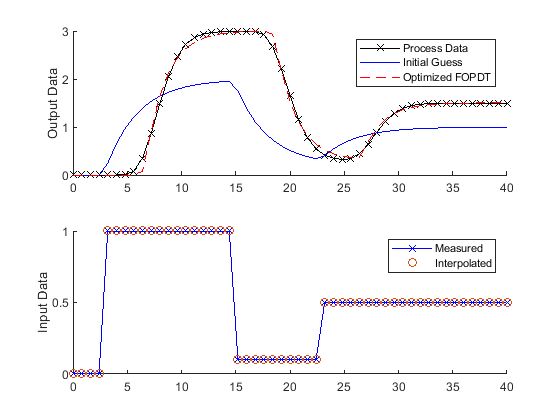


figure(2);
subplot(2,1,1)
hold on
p1 = plot(t, yp,'kx-');
p2 = plot(t, ym1, 'b-');
p3 = plot(t, ym2, 'r--');
legend([p1, p2, p3], {'Process Data', 'Initial Guess', 'Optimized FOPDT'})
ylabel('Output Data')

subplot(2,1,2)
hold on
p4 = plot(t,u,'bx-');
p5 = plot(t, interp1(t, u, t), 'o');
legend([p4, p5], {'Measured', 'Interpolated'})
ylabel('Input Data')

function dydt = process(t, y, n, u, Kp, taup)
    % arguments
    %  y[n] = outputs
    %  t    = time
    %  n    = order of the system  
    %  u    = input value
    %  Kp   = process gain
    %  taup = process time constant
    % equations for higher order system
    dydt = zeros(n,1);
    %size of y is determined by inital conditions
    % calculate derivative
    dydt(1,1) = (-y(1) + Kp * u)/(taup/n);
    for i = 2:n
       dydt(i,1) = (-y(i) + y(i-1))/(taup/n);
    end
end

function yp = sim_process_data(u, delta_t, ns)
    % higher order process
    n=10;       % order
    Kp=3.0;    % gain
    taup=5.0;   % time constant
    % storage for predictions or data
    yp = zeros(1,ns+1);  % process
    for i = 1:ns+1
        if i==1
            yp0 = zeros(1, n);
        end
        ts = [delta_t*(i-1),delta_t*i];
        [t, y] = ode45(@(t, y) process(t, y, n, u(i), Kp, taup), ts, yp0);  
        yp0 = y(end,:);
        yp(i) = y(2, n);
    end
end

% define first-order plus dead-time approximation    
function dydt = fopdt(t, y, u, tvals, Km,taum,thetam, yp0, u0)
    % arguments
    %  y      = output
    %  t      = time
    %  uf     = input linear function (for time shift)
    %  Km     = model gain
    %  taum   = model time constant
    %  thetam = model time constant
    % time-shift u
    try
        if (t-thetam) <= 0
            um = interp1(tvals, u, 0.0);%% IS A FUNCTION
        else
            um = interp1(tvals, u, t-thetam); %% IS A FUNCTION
        end
    catch 
        disp('Error with time extrapolation: ' + t )
        %DIFFERENT
        um = u0;
    end
    % calculate derivative
    %DIFFERENT
    dydt = (-(y-yp0) + Km * (um-u0))/taum;
end

% simulate FOPDT model with x=[Km,taum,thetam]
function ym = sim_model(x) %, ns, delta_t, u, tvals)
    % input arguments
    global yp ns delta_t u tvals yp0 u0
    Km = x(1);
    taum = x(2);
    thetam = x(3);
    % storage for model values
    ym = zeros(1, ns);  % model
    % initial condition
    ym(1) = yp0;
    % loop through time steps    
    for i = 1:ns-1
        ts = [delta_t*(i-1),delta_t*i];
        [t, y1] = ode45(@(t, y) fopdt(t, y, u, tvals, Km,taum,thetam, yp0, u0), ts, ym(i));
        ym(i+1) = y1(end);
    end
end

function obj = objective(x)
    global yp
    % simulate model
%     ns = ns; 
%     delta_t = delta_t;
%     u = u;
%     tvals = tvals;
    ym = sim_model(x); %, ns, delta_t, u, tvals)
    % calculate objective
    obj = 0.0;
    for i = 1:length(ym)
        obj = obj + (ym(i)-yp(i))^2;    
    end
end